clear all
close all

image = 'Testimages/Color1.jpg';
I = imread(image);% Detect the checkerboard points.

[imagePoints,boardSize] = detectCheckerboardPoints(I);


Points = [1; boardSize(1,1)-1; length(imagePoints)-(boardSize(1,1)-2); length(imagePoints)]

Points =      1
     5
    41
    45


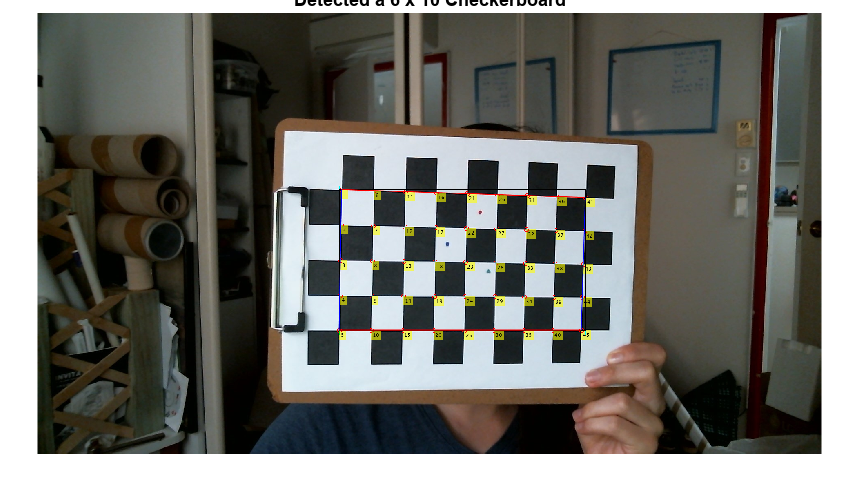


%Finding the bounding box of the checkerboard
TopLeft = min(imagePoints);
BottomRight = max(imagePoints);
BottomLeft = [TopLeft(1,1), BottomRight(1,2)];
Corners = [imagePoints(Points(1),:); imagePoints(Points(2),:); imagePoints(Points(3),:) ;imagePoints(Points(4),:)];
% Adding Markers
J = insertText(I,imagePoints,1:size(imagePoints,1));
J = insertMarker(J,imagePoints,'o','Color','red','Size',5);

J = insertMarker(J,TopLeft,'plus','Color','cyan','Size',10);
J = insertMarker(J,BottomRight,'plus','Color','cyan','Size',10);

J = insertMarker(J,BottomLeft,'plus','Color','green','Size',10);

J = insertMarker(J,[imagePoints(Points(1),:)],'plus','Color','yellow','Size',10);

J = insertShape(J,'rectangle',[TopLeft abs(BottomRight-TopLeft)],'LineWidth',2,'Color','black');

J = insertShape(J,'Line',[[Corners(1,:)] [Corners(2,:)]],'LineWidth',2,'Color','blue');
J = insertShape(J,'Line',[[Corners(3,:)] [Corners(4,:)]],'LineWidth',2,'Color','blue');

J = insertShape(J,'Line',[[Corners(1,:)] [Corners(3,:)]],'LineWidth',2,'Color','red');
J = insertShape(J,'Line',[[Corners(2,:)] [Corners(4,:)]],'LineWidth',2,'Color','red');


imshow(J);
title(sprintf('Detected a %d x %d Checkerboard',boardSize));

%figure(1);


a = Corners(1,1)-Corners(2,1)

a = 5.6520

b = Corners(1,2)-Corners(2,2)

b = -343.7869

c = sqrt(a^2+b^2)

c = 343.8334


a2 = Corners(3,1)-Corners(4,1)

a2 = 10.7324

b2 = Corners(3,2)-Corners(4,2)

b2 = -324.6805

c2 = sqrt(a2^2+b2^2)

c2 = 324.8579


diff = c - c2

diff = 18.9755

roi = [TopLeft abs(BottomRight-TopLeft)];
